## Matlab code examples from Chapter 2 of the "Robotics, Vision and Control" book

set(0, 'DefaultLineLineWidth', 2);
clear all
clc

### p24-25 (2.1.1.1) 

R = rot2(0.2)                           %%%rotation matrix R with the angle specified in radians

R =     0.9801   -0.1987
    0.1987    0.9801


det(R)                                  %%% property of R is the det equals to 1 

ans = 1

det(R*R)                                %%% the product of rotation matrix multiplication is also a rotation matrix

ans = 1

syms theta                              %%% the toolbox also supports symbolic mathematics

R = rot2(theta)                         %%% symbolic mathematics example (instead of numerical value in rad)

$$R = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

R*R

$$ans = \left(\begin{array}{cc} {\cos\left(\theta \right)}^{2}-{\sin\left(\theta \right)}^{2} & -2\,\cos\left(\theta \right)\,\sin\left(\theta \right)\\ 2\,\cos\left(\theta \right)\,\sin\left(\theta \right) & {\cos\left(\theta \right)}^{2}-{\sin\left(\theta \right)}^{2} \end{array}\right)$$

simplify(R*R)                           %%% simplify the presented results

$$ans = \left(\begin{array}{cc} \cos\left(2\,\theta \right) & -\sin\left(2\,\theta \right)\\ \sin\left(2\,\theta \right) & \cos\left(2\,\theta \right) \end{array}\right)$$

det(R)

$$ans = {\cos\left(\theta \right)}^{2}+{\sin\left(\theta \right)}^{2}$$

simplify(det(R))          

$$ans = 1$$

### p24-25 (2.1.1.2) Skew Symmetric matrix Representation

R = rot2(0.3)                           %%% rotation matrix for 0.3 rads

R =     0.9553   -0.2955
    0.2955    0.9553


S = logm(R)                             %%% compute the logarithm of this matrix using the matlab function logm. 

S =          0   -0.3000
    0.3000         0


                                        %%% The result is a simple matrix with two elements 
                                        %%% having a magnitude of 0.3,
                                        %%% which intriguingly is the original rotation angle

vex(S)                                  %%% This matrix has a zero diagonal and is an example of a 2 × 2 skew-symmetric matrix

ans = 0.3000

                                        %%% The matrix has only one unique element and we can unpack it using the Toolbox function vex

expm(S)                                 %%% The inverse of a logarithm is exponentiation and using the builtin MATLAB matrix exponential function expm

ans =     0.9553   -0.2955
    0.2955    0.9553


R = rot2(0.3)                           %%% original rotation matrix

R =     0.9553   -0.2955
    0.2955    0.9553


%%%  original rotation matrix is equivalent to  this command. Check the rotation matrix definition with the exponential
R = expm(skew(0.3))

R =     0.9553   -0.2955
    0.2955    0.9553


### p27-29 (2.1.2.1) &  (2.1.2.2) 

clear all
clc

We create a homogeneous transformation which represents a **translation of (1, 2) **followed by a** rotation of 30°**.

The function transl2 creates a relative pose with a finite translation but zero rotation, while trot2 creates

a relative pose with a finite rotation but zero translation.


T1 = transl2(1, 2) * trot2(30, 'deg')   

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


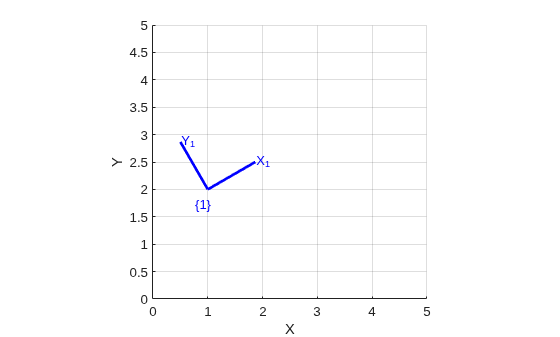

gca.LineWidth=20; 
plotvol([0 5 0 5]);                 %%% plot relative to the world coordinate frame
trplot2(T1, 'frame', '1', 'color', 'b', 'thick', 2)

We create another relative pose which is represents a displacement of (2, 1) and zero rotation

T2 = transl2(2, 1)

T2 =      1     0     2
     0     1     1
     0     0     1


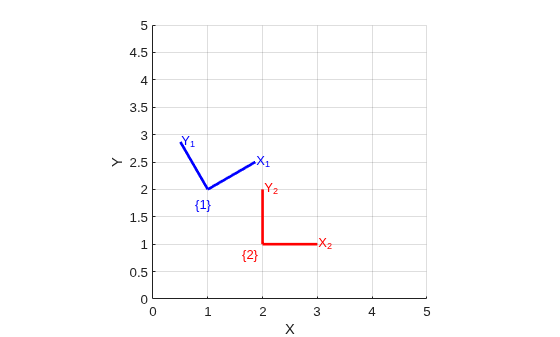

trplot2(T2, 'frame', '2', 'color', 'r', 'thick', 2);

we can compose the two relative poses

T3 = T1*T2                               

T3 =     0.8660   -0.5000    2.2321
    0.5000    0.8660    3.8660
         0         0    1.0000


We see that the displacement of (2, 1) has been applied **with respect to frame {1}**. It is

important to note that our final displacement is not (3, 3) because the displacement

is with respect to the rotated coordinate frame.

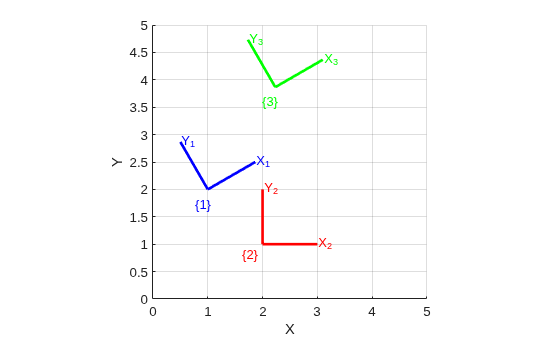

trplot2(T3, 'frame', '3', 'color', 'g', 'thick', 2);

noncommutativity of composition is demonstrated

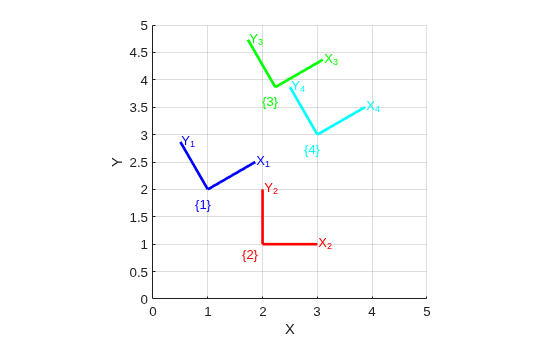

T4 = T2*T1;                              
trplot2(T4, 'frame', '4', 'color', 'c', 'thick', 2); %%% and we see that frame {4} is different to frame {3}.

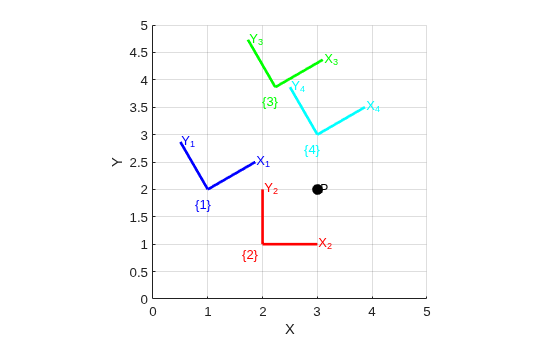

P = [3 ; 2 ];                            %%% Now we define a point (3, 2) relative to the world frame which is a column vector
plot_point(P, 'label', 'P', 'solid', 'ko');

 determine the coordinate of the point with respect to frame {1}

P1 = inv(T1) * [P; 1]                    %%% where we first converted the Euclidean point coordinates to homogeneous form by appending

P1 =     1.7321
   -1.0000
    1.0000


                                         %%% a one on vector. The result is also in homogeneous form and has a negative y-coordinate in frame {1}

Using the Toolbox we could also have expressed this (Homogeneous to Euclidean)

h2e( inv(T1) * e2h(P) )                 

ans =     1.7321
   -1.0000


### Rotations around Point

First we create and plot a reference coordinate frame {0} and a target frame {X}

clf                                      

axis equal
plotvol([-5 5 -4.5 4.5]);
%%
T0 = eye(3,3)                           %%% define frame 0

T0 =      1     0     0
     0     1     0
     0     0     1


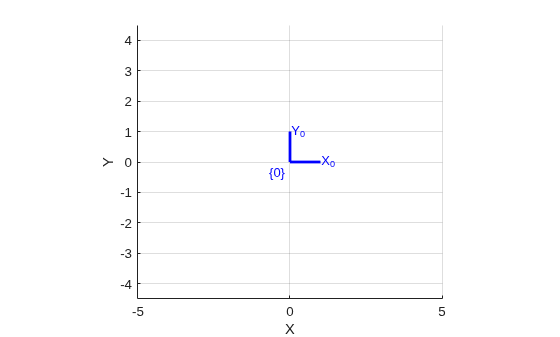

%%
trplot2(T0, 'frame', '0', 'thick', 2);              %%% plot frame 0

X = transl2(2, 3)                       %%% define frame X

X =      1     0     2
     0     1     3
     0     0     1


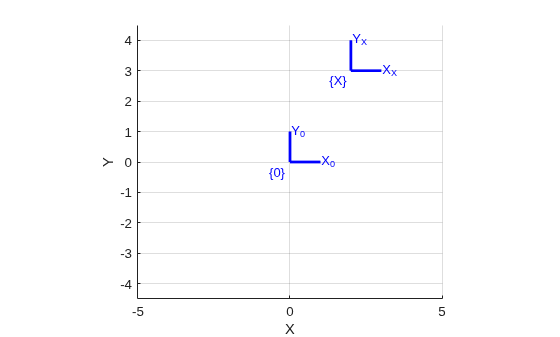

%%
trplot2(X, 'frame', 'X', 'thick', 2);               %%% plot frame X

R = trot2(2)                           %%% rotation of 2 radians (approximately 115°)           

R =    -0.4161   -0.9093         0
    0.9093   -0.4161         0
         0         0    1.0000


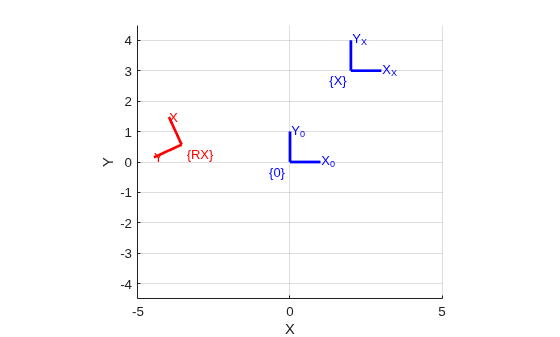

trplot2(R*X, 'framelabel', 'RX', 'color', 'r', 'thick', 2);  %%% plot the effect of the two possible orders of composition (1)

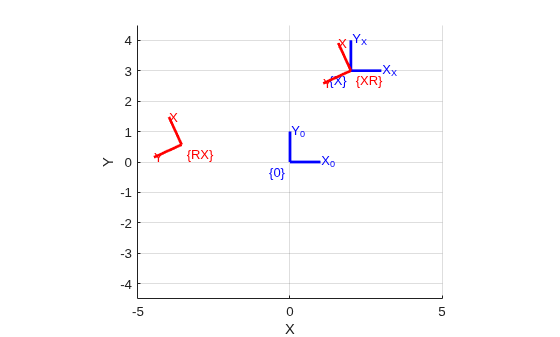

trplot2(X*R, 'framelabel', 'XR', 'color', 'r', 'thick', 2);  %%% plot the effect of the two possible orders of composition (2)

We see that the frame {RX} has been rotated about the origin, while frame {XR} has been rotated about the origin of {X}

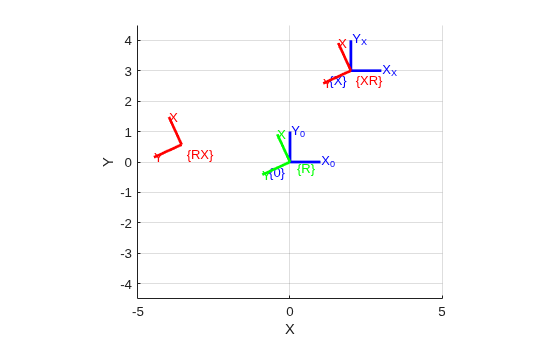

trplot2(R, 'framelabel', 'R', 'color', 'g', 'thick', 2);  

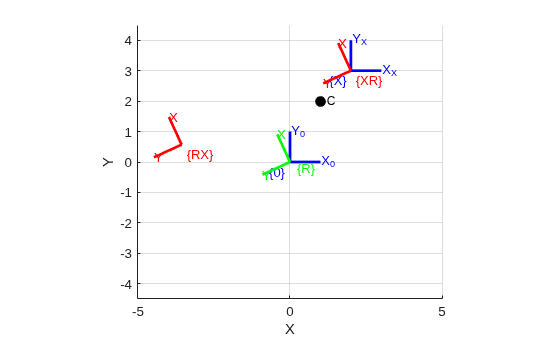

C = [1 2]';                                      %%% rotate a coordinate frame about an arbitrary point. Establish a new point C
%%
plot_point(C, 'label', ' C', 'textcolor', 'k', 'solid', 'ko') %%% display the point

RC = transl2(C) * R * transl2(-C)                %%% then compute a transform to rotate about point C

RC =    -0.4161   -0.9093    3.2347
    0.9093   -0.4161    1.9230
         0         0    1.0000


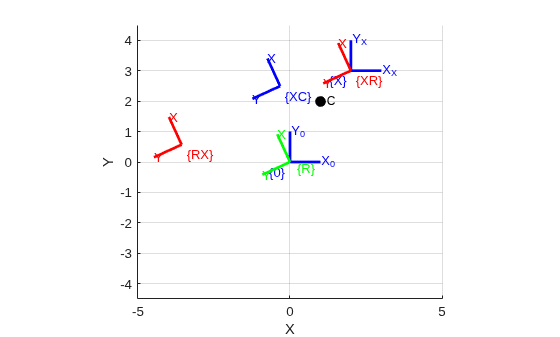

trplot2(RC*X, 'framelabel', 'XC', 'yellow', 'r', 'thick', 2); %%% display the result

### p34-37 (2.2.1.1) 

clear all
clc
clf

%%%rotation matrix around x axis for 45 degrees
R = rotx(pi/2)                                  

R =      1     0     0
     0     0    -1
     0     1     0


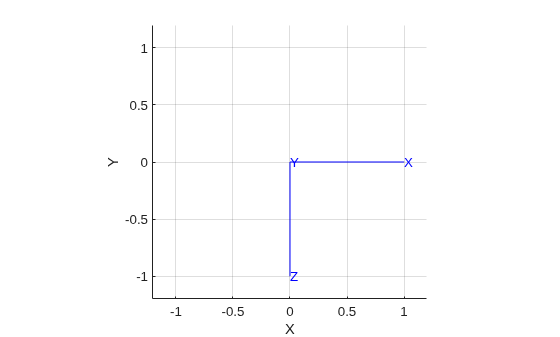

%%% coordinate frame can be displayed graphically
trplot(R)                                        

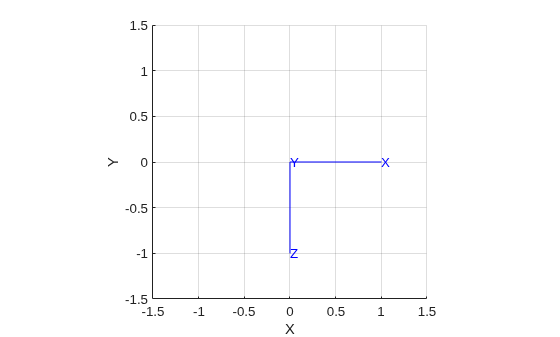

%%% animate a rotation using the Toolbox function tranimate
tranimate(R)

%%% rotate previous frame around y axis
R = rotx(pi/2) * roty(pi/2)

R =      0     0     1
     1     0     0
     0     1     0


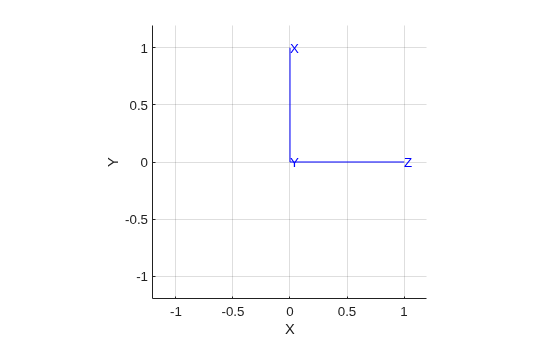

trplot(R) 

%%% The noncommutativity of rotation can be shown by reversing the order of the rotations above
roty(pi/2)*rotx(pi/2)                            

ans =      0     1     0
     0     0    -1
    -1     0     0


%%% ZYZ sequence for Euler rotation 
R =  rotz(0.1) * roty(0.2) * rotz(0.3)

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


%%% same as previous command but more compact form
R = eul2r(0.1, 0.2, 0.3)                       

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


%%% The inverse problem is finding the Euler angles that correspond to a given rotation matrix
gamma = tr2eul(R)                       

gamma =     0.1000    0.2000    0.3000


%%% if theta negative
R = eul2r(0.1 , -0.2, 0.3)                       

R =     0.9021   -0.3836   -0.1977
    0.3875    0.9216   -0.0198
    0.1898   -0.0587    0.9801


%%% the inverse function returns a positive value for theta and different values for phi and psi
tr2eul(R)                                       

ans =    -3.0416    0.2000   -2.8416


However the rotation matrix is the same. 

The two different sets of Euler angles correspond to one rotation matrix.

The mapping from a rotation matrix to Euler angles is not unique

and the Toolbox always returns **a positive value for theta**

eul2r(ans)                                       

ans =     0.9021   -0.3836   -0.1977
    0.3875    0.9216   -0.0198
    0.1898   -0.0587    0.9801


R = eul2r(0.1, 0, 0.3)                           %%% for theta=0

R =     0.9211   -0.3894         0
    0.3894    0.9211         0
         0         0    1.0000


%%% the inverse function returns different angles. 
%%% The rotation matrix is a function of the sum 
% of phi and psi angles. Therefore the inverse operation can do no more
tr2eul(R)                          

ans =          0         0    0.4000


### Roll-Pitch-Yaw Angles

%% p38 
clear all
clc

When describing the attitude of a **robot gripper** (z-axis points forward and x-axis is either up/down) --> **XYZ angle sequence**

 When describing the attitude of a **vehicle** (x points forward and z-axis up/down) --> **ZYX angle sequence**

**ZYX sequence **is the **default **for the toolbox

R = rpy2r(0.1, 0.2, 0.3) % roll, pitch, yaw

R =     0.9363   -0.2751    0.2184
    0.2896    0.9564   -0.0370
   -0.1987    0.0978    0.9752


%inverse calculation (from rotation matrix to rpy angles). The roll-pitch-yaw sequence allows all angles to have
%arbitrary sign and it has a singularity when theta=±pi/2 which is fortunately outside the range of feasible 
%attitudes for most vehicles.
gamma = tr2rpy(R)

gamma =     0.1000    0.2000    0.3000


reading STL models......
Supermarine Spitfire Mk VIII by Ed Morley @GRABCAD
Gimbal models by Peter Corke using OpenSCAD


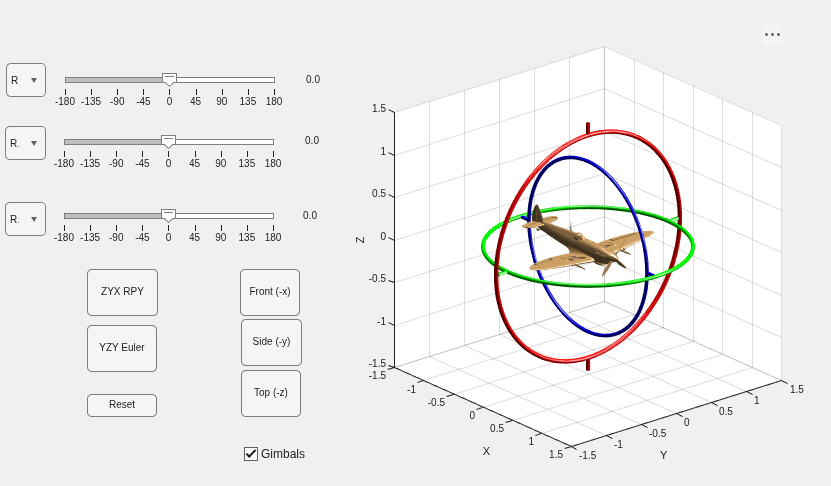

% Interactive Graphical Tool
tripleangle_App

### Quaternions

%In the Toolbox quaternions are
%implemented by the UnitQuaternion class and the
%constructor converts a passed argument such as a rotation matrix to a unit quaternion
q = UnitQuaternion( rpy2tr(0.1, 0.2, 0.3)  ) 

 
q = 
 
0.98335 < 0.034271, 0.10602, 0.14357 >
 


%%% Quaternion multiplication is invoked through the overloaded multiplication operator
q = q * q

 
q = 
 
0.93394 < 0.0674, 0.20851, 0.28236 >
 


% inverse opearation. The conjugate of a unit quaternion
inv(q)

 
ans = 
 
0.93394 < -0.0674, -0.20851, -0.28236 >
 


% Multiplying a quaternion by its inverse yields the identity quaternion
q*inv(q) 

 
ans = 
 
1 < 0, 0, 0 >
 


% which represents a null rotation
q/q

 
ans = 
 
1 < 0, 0, 0 >
 


%The quaternion can be converted to an orthonormal rotation matrix
q.R

ans =     0.7536   -0.4993    0.4275
    0.5555    0.8315   -0.0081
   -0.3514    0.2436    0.9040


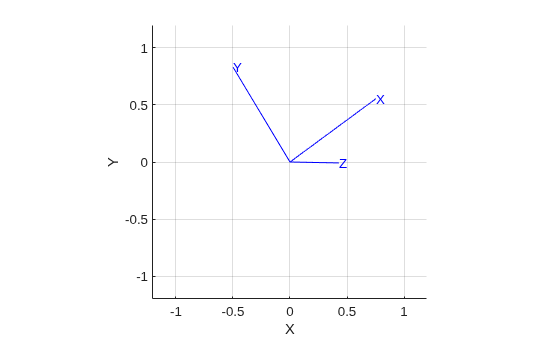

%and we can also plot the orientation represented by a quaternion
q.plot()

% A vector is rotated by a quaternion using the overloaded multiplication operator
q*[1 0 0]' 

ans =     0.7536
    0.5555
   -0.3514


%% 47 (2.2.2.1)
clear all
clc

settingsObj = settings;
settingsObj.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;

T = transl(1, 0, 0) * trotx(pi/2) * transl(0, 1, 0)         %%% The Toolbox has many functions to create homogeneous transformations

T =      1     0     0     1
     0     0    -1     0
     0     1     0     1
     0     0     0     1


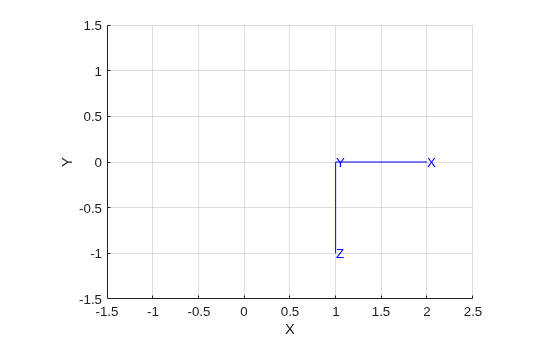

tranimate(T)                         % translation column vector component of T                       %%% The function transl creates a relative pose with a finite translation but no rotation,

                                                            %%% while trotx creates a relative pose corresponding to a rotation of pi/2 about the x-axis with zero translation.
                                                            %%% The result, as shown in the last column of the resulting matrix is a translation of 1 unit along the original x-axis and
                                                            %%% 1 unit along the original z-axis. The orientation of the fi nal pose shows the effect of the rotation about the x-axis.

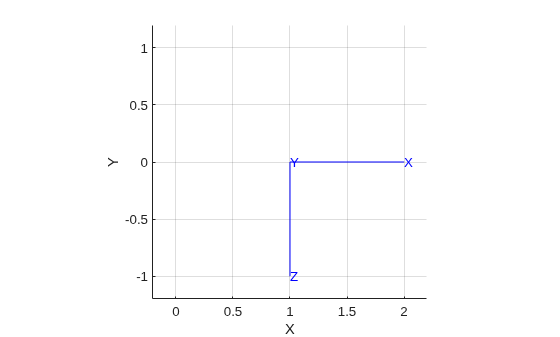

trplot(T) %plot

t2r(T)    %rotation matrix component of T

ans =      1     0     0
     0     0    -1
     0     1     0


transl(T) %translation column vector component of T      

ans =      1
     0
     1
